# Explore a Refrigeration Model

[⇦ Overview](matlab: OpenOverview) 

In this tutorial, we will investigate a closed-loop refrigeration system to keep a thermal mass within a specific temperature range for a prescribed heat load. An example of such a system is a battery chiller cold plate. A schematic for this system is shown in Figure 1. This system is composed of four primary components which convey a working fluid (refrigerant) and heat from the cold plate to the environment.

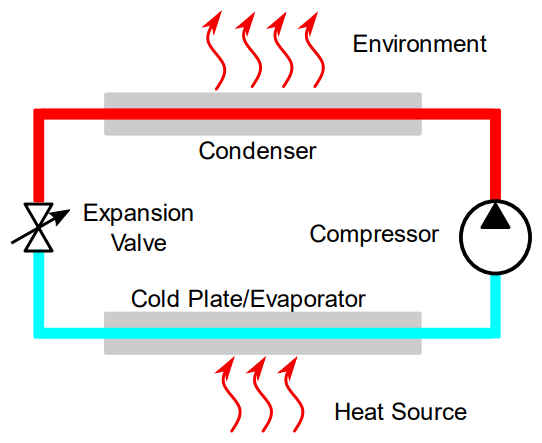

Figure 1: System model overview. The cold plate, which is heated externally, is in thermal contact with a refrigeration loop, which expels its heat to the environment. The refrigeration loop contains four main components: an evaporator, a condenser, a compressor, and an expansion valve.

## System Components Overview

The **compressor** heats the cold evaporated fluid, pressurizes it, and transports it to the condenser side, where the fluid can give its heat to the environment. The refrigerant enters and leaves the compressor as super-heated vapor. The compressor we will model will be capable of running at different speeds and will have a flow rate that depends on the operating speed and the pressure ratio between the condenser and evaporator.

The **condenser** allows the high-pressure refrigerant to change phase to liquid by exchanging heat with a separate, cooler stream. The refrigerant enters the condenser as a super-heated vapor and exits as a sub-cooled liquid. Like an evaporator, this device consists of two working fluid channels separated by a thin conductive wall. In this case, the fluid will exchange heat with a moist air stream, which has a constant entrance temperature, humidity, and flow rate.

The **expansion valve** regulates the mass flow and pressure difference between the condenser and evaporator. Expansion valves can be either Thermal Expansion type (TXV) or Electronic Expansion type (EEV). The refrigerant enters the valve as a sub-cooled liquid and exits in a vapor-liquid equilibrium state.

The **evaporator** is a device that conveys heat to a refrigerant at low temperature, pressure, and quality to vaporize it. The refrigerant typically enters the evaporator in a vapor-liquid equilibrium state, leaving it as a super-heated vapor. Often the evaporator consists of two isolated working fluid channels in thermal contact via a highly conductive wall. Here, however, we will represent the other “side” of the evaporator as the cold plate connected to a 1 kW heat load.

The **cold plate** for this example is tied to a heat source, which we will model as a boundary condition. Since we will just be setting the value mathematically, we don't need to worry about the physical details of where the heat comes from. In a larger scale model, the heat would likely come from another fluid like ethylene glycol or oil circulating through heat-generating devices. In our model, the cold plate will be represented by a 10 kg thermal mass made from aluminum.

### Simulation Goal

Our specific objective is to build a refrigeration system that can maintain a 10 kg aluminum cold plate at 5$^{\circ}$C. This cold plate will be attached to a heat source with a nominal value of 1 kW. The system needs to be able to operate between environmental temperatures of 15$^{\circ}$C and 40$^{\circ}$C.

## The Working Fluid

The first step in modeling a refrigeration system is to choose the working fluid. This choice depends on many factors, including the expected operating range, cost, and environmental considerations. In this example, we will use R-1234yf for the refrigerant, which is commonly used in automotive applications for systems within our range of temperatures. At the end of the script, we will consider other possibilities. The pressure-enthalpy diagram for this fluid is shown in Figure 2. From this diagram, we can see the refrigerant has vapor-liquid states for temperatures above our maximum expected environmental temperature of 40$^{\circ}$C (313.15 K), allowing the condenser to operate properly below its critical point.

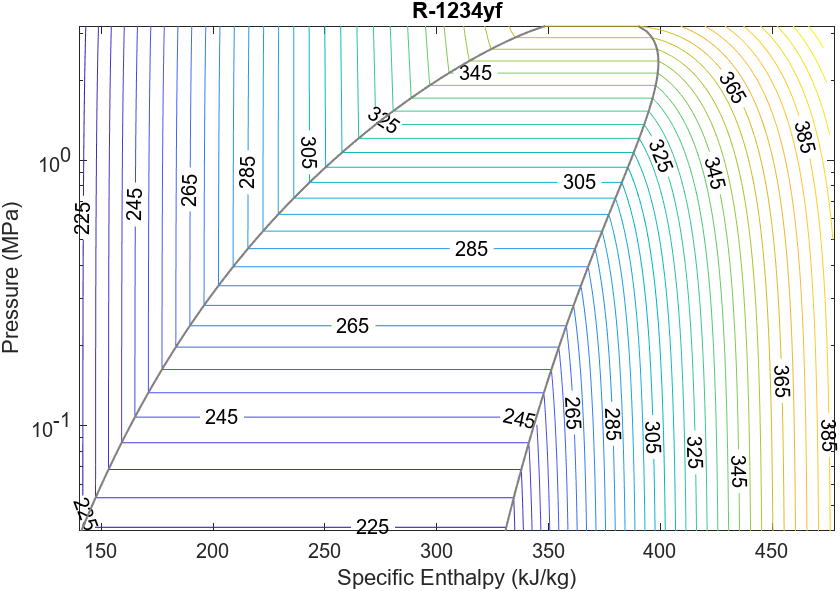

Figure 2: Pressure-enthalpy diagram for the R-1234yf working fluid.

To simulate a fluid network, it is necessary to provide Simscape with the properties for the fluid to be used. For a refrigerant, these properties include the temperature/pressure phase coexistence curve, the specific energy, specific enthalpy, specific volume, viscosity, etc. These properties must be provided in the liquid, vapor, and vapor-liquid coexistence regions as they determine the flow and heat transfer of the fluid according to the local thermodynamic state. For two-phase systems in Simscape, we use a mean-field model for all thermodynamic computations with pressure and specific internal energy as the state variables. All other properties are computed by interpolation on the tables provided.

** Exercise: **By adding sensors to our refrigerator model, we can determine the values of thermodynamic quantities at various points in the system. Running this section will open a pop-up window showing the pressure-enthalpy diagram in Figure 2. 

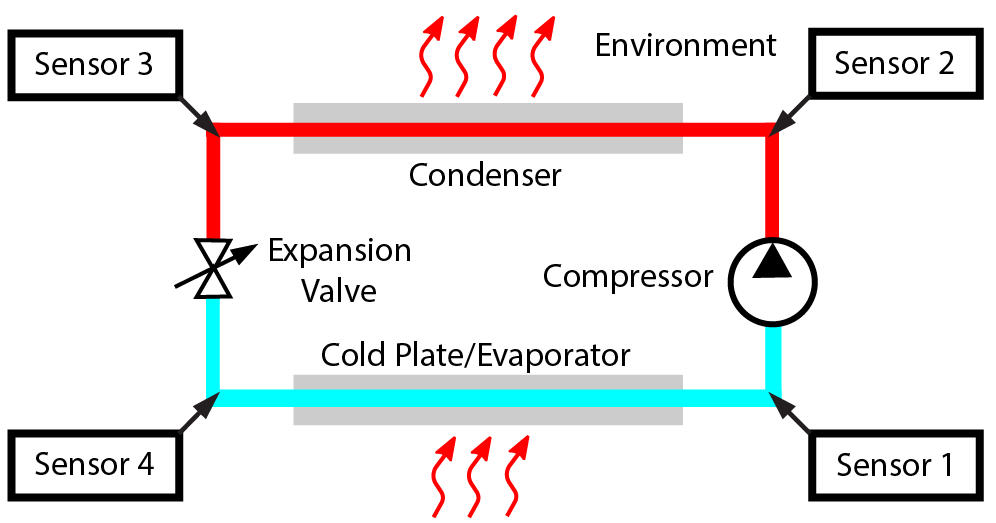

Figure 3: A refrigeration cycle with four sensors attached, one between each pair of adjacent components.

What values do you think each sensor in Figure 3 would register for a well-tuned refrigeration cycle? For each sensor, click the pop-up window to add a point to the pressure-enthalpy diagram. Double-click to finish data collection. Close the figure window and return to the script.

[x,y] = collectData();

 
tf = checkEstimatedCycle(x,y);
if all(tf)
    sensor4 =  0;
    checkSensorPoints(sensor4,x,y)
else
    disp("You must successfully identify potential values before you can match sensors to points.")
end

  **Try**. 

- Open Simscape and look at the model. Can you identify the four components in Figure 1?

fullmdl = 'ModelFridge';
open_system(fullmdl);

**Note 1:** The block elements from the thermal library are orange, while the block elements from the fluids library are blue. This color-coding by type can help us track how particular physical elements flow through our system. 

**Note 2:** This model will give you errors (red shading around blocks) because you still need to determine all the parameters necessary to run it. That will come later in the script. You will set the first parameter right now:

         2. Find the Two-Phase Fluid Predefined Properties (2P) block. It looks like this: 

and is labeled "Two-Phase Fluid Choice".

        3. Double-click the block to open its properties table. There are a variety of standard fluids included as options. The default fluid for this block is water, but there are better choices for the working fluid in a refrigerator in this operating domain. Select "R-1234yf" from the drop-down. Are there other familiar substances included as options?

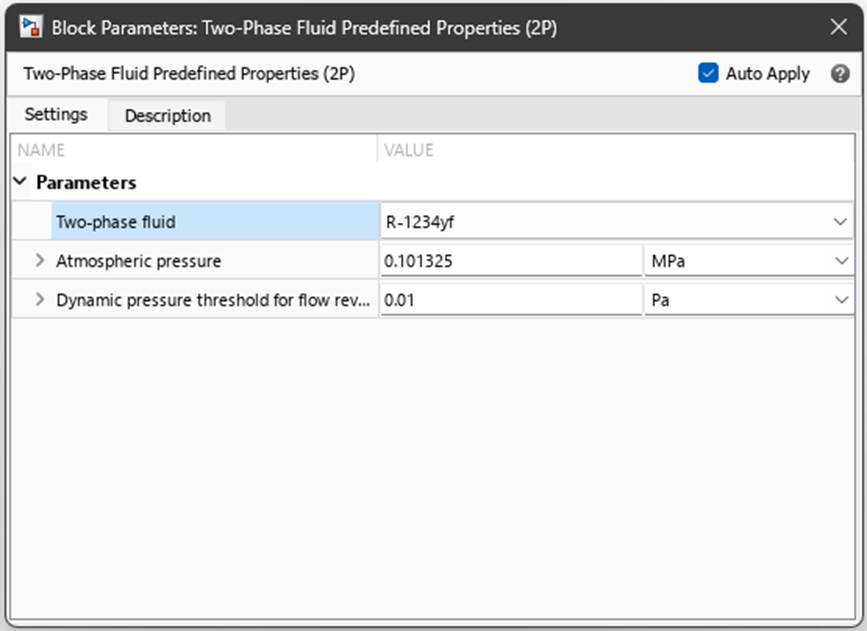

## Modeling the Cold Plate and Evaporator

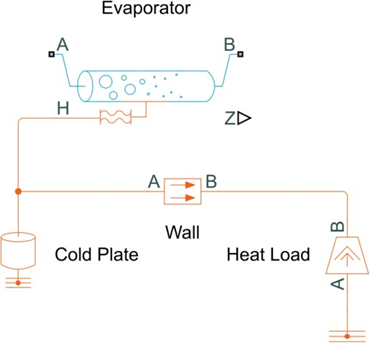       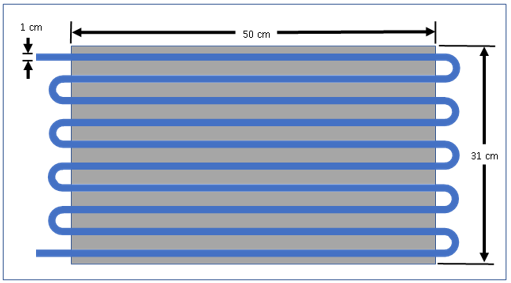

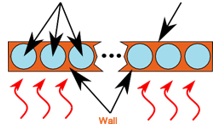

Figure 3: Above, the first image depicts the Simulink block diagram for the cold plate and evaporator. The second is a physical representation of the cold plate and evaporator. On the bottom is a cutaway of the cold plate looking down the refrigerant tubes. The cold plate consists of a 50 cm x 31 cm x 2.4 cm aluminum block with 1 cm diameter channels bored through it. These channels are connected in a serpentine path with brazed copper tubing. The total tube length is approximately 5 m. The refrigerant enters one end in a vapor-liquid equilibrium state leaving the other as super-heated vapor.

### Determining Anticipated Parameters

To test individual design components, we need to provide boundary conditions, initial conditions, and a flow rate to ensure the heat exchange is 1 kW in the worst-case scenario, i.e., when the environmental temperature is 40$^{\circ}$C.

We need to access additional information from a reference database (e.g., thermodynamic tables, REFPROP, or CoolProp) by making some static assumptions to determine the initial and boundary conditions. 

** Exercise: **Fill in the details needed to complete the calculations for each of the assumptions.

**Assumption:** The condensing temperature is 55C, sufficiently high to expel enough heat to the environment.

While the condensing temperature is given in Celsius, all thermodynamic calculations are performed in Kelvin. Set up a proper unit conversion and update the comment tracking the unit.

% Replace the 0 with the value for converting Celsius to Kelvin
kelvinCelsiusShift = 0;      % +: C -> K  and -: K -> C
Tcond = 55                   % C

The pressure values in CoolProp are given in pascals. Convert the initial pressure result, `Pcond`, into units of kilopascals:

load R1234yfData Pcond    % Pa
% Convert Pcond from Pa to kPa below
% kPa

**Assumption:** The condenser output is 8C subcooled.

While the condensing temperature is the exact value at which our chosen refrigerant condenses, we cannot assume that our environment will be precisely controlled. By cooling the output of the condenser to a chosen value lower than the condensing temperature, we can be sure that even with changes to the environment of our refrigerator, the process will still proceed through the expected thermodynamic states. This is called subcooling. Define the value `Tsc` to be the subcooled temperature in Kelvin.

Tsc = Tcond;                 % K

The enthalpy values in CoolProp are stored in $\frac{\text{J}}{\text{kg}}$. Take the enthalpy value for R1234yf at the subcooled temperature and the condenser pressure from CoolProp and called `hin` and convert the units from $\frac{\text{J}}{\text{kg}}$ into $\frac{\text{kJ}}{\text{kg}}$ and save this updated value to `hin`.

load R1234yfData hin             % J/kg
% kJ/kg

**Assumption:** The evaporating temperature is -10C, sufficiently low to transfer heat from the plate at 5C.

All thermodynamic calculations are performed in Kelvin. Set up a proper unit conversion for `Tevap` and update the comment tracking the unit.

Tevap = -10;  % C

The pressure values in CoolProp are given in pascals. Convert the evaporating pressure result, `Pevap`, into units of kilopascals:

load R1234yfData Pevap          % Pa
% kPa

**Assumption:** The evaporator outlet temperature has 5C superheat.

While the evaporating temperature is the exact value at which our chosen refrigerant vaporizes, we cannot assume that our environment will be precisely controlled. By cooling the output of the evaporator a chosen amount higher than the evaporating temperature, we can be sure that even with changes to the environment of our refrigerator, the process will still proceed through the expected thermodynamic states. This is called superheating. Define the value `Tsh` to be the superheated temperature in Kelvin.

% K

load R1234yfData hout            % J/kg
% kJ/kg

if exist("Tsh","var")
    checkMyParams(hout,Tsh,Pevap,Tevap,hin,Tsc,Pcond,Tcond,kelvinCelsiusShift)
else
    warning("You must complete this exercise to continue.")
end

Once we have the initial and boundary conditions, we must determine the approximate mass flow we expect from the system in steady state. We can compute this with the standard formula for heat transfer in an evaporating fluid

                   
$$Q = \dot{m}_{\text{ref}}\left(h_{\text{out}}-h_{\text{in}}\right)$$
                  
$$(\star)$$


In this case, let's include [units](https://www.mathworks.com/help/symbolic/units-of-measurement-tutorial.html) directly with our values during the computation.

% Declare a symbolic unit system
u = symunit;
Q = 1*u.kW;                % kW
hin = hin*u.kJ/u.kg        % kJ/kg
hout = vpa(hout)*u.kJ/u.kg      % kJ/kg
mdotref = Q/(hout-hin)     % kW/(kJ/kg)

We want to keep track of our units; this can provide a handy double-check on our calculations. The units of $\frac{\text{kW}\cdot\text{kg}}{\text{kJ}}$ are not optimal. We would expect the units of $\dot{m}_{\text{ref}}$ to be $\frac{\text{mass}}{\text{time}}$. We can check that these are equivalent forms by simplifying the units we found:

mdotref = simplify(mdotref)

With this information, we are ready to build the test harness model for our evaporative cold plate model. 

#### Testing the Evaporator

  **Try**. Open the evaporator component using the parameter values we just determined. 

evaporatorParams
mdl = 'ModelFridgeEvaporator';
open_system(mdl);

 **Reflect**. There are inlet/outlet pipes in this model that are not in the full model. Why?

#### Trying out the Simulation

Step 1: Run the model using the Run icon,  . 

Step 2: Double-click on the P-H Diagram (2P) block to open the P-H Diagram plot. Reset the time to 0 and watch the values throughout the simulation. 

** Exercise.**

a) What is the pressure in kPa in the evaporator during this simulation?

myEx1a = 0;
checkEvaporatorExercise(myEx1a,"a)")

b) What is the lowest enthalpy value in kJ/kg?

myEx1b = 0;
checkEvaporatorExercise(myEx1b,"b)")

c) What is the highest enthalpy value in kJ/kg?

myEx1c = 0;
checkEvaporatorExercise(myEx1c,"c)")

d) Looking at the output of the scope, is the temperature in the evaporator warmer or colder than the freezing temperature of water?

myEx1d = "default";
checkEvaporatorExercise(myEx1d,"d)")
 

  **Reflect**.

- Which states of matter are present in this system at the inlet? At the outlet?

- Why does the simulation create a static result?

### ** Example:** Extracting data from a simulation

% Check that you have run the simulation
if ~exist("out","var")
    warning("You didn't run the model from Simulink.")
else
    % Timing data
    tData = out.simlog_EvaporatorHarness.Evaporator.z_mix.series.time;

    % The fraction of vapor-liquid mix at each time step
    z_mixData = out.simlog_EvaporatorHarness.Evaporator.z_mix.series.values;

    % The fraction of superheated vapor at each time step
    z_vapData = out.simlog_EvaporatorHarness.Evaporator.z_vap.series.values;
end

**Exercise. **Use this data to plot the fractions of vapor-liquid and superheated vapor in the evaporator component in steady state. 

Your result should look something like this:

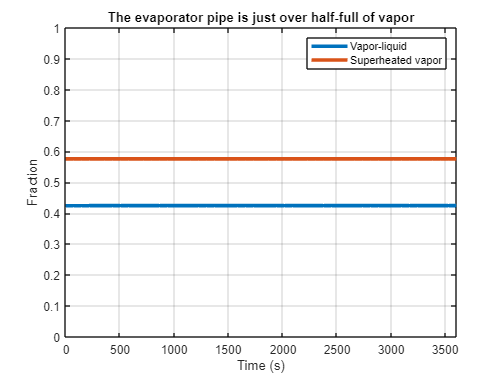

## Compressor Model

Now we can move from the Evaporator subsystem to the Compressor subsystem. 

In our calculations in the previous section, we estimated the mass flow rate of the compressor via Equation $(\star)$ to be:

mdotref

 We now need to define a compressor that can deliver this mass flow rate between the estimated evaporator pressure, `Pevap`, and the condenser pressure, `Pcond`, at the specific enthalpy, `hout`, of the refrigerant that is coming from the evaporator.

### ** Example:** Programmatically Testing the Compressor

As with the evaporator, testing the compressor requires adding additional sensors and comparing the simulation results to expected values. For the compressor, we'll test a range of values programmatically.

% Load the parameters
compressorParams;

% Open the model of the compressor alone with sensor attachments
mdl = 'ModelFridgeCompressor';
open_system(mdl);

#### Set up the design of experiments

Set up the design of experiments (DOE) for the parameter sweep. The goal is to sweep the compressor speed from 400 to 4000 rpm and the outlet pressure from 800 to 2400 kPa. This will exercise the compressor across pressure ratios from about 3 to 11, which should provide a reasonable map for the expected operating conditions. The key lines for setting up the DOE are initializing the set of values and creating the matrices of all sets of parameters.

N_lis = 400:400:4000;             % [rpm]
p2_lis = 800:400:2400;            % [kPa]

Programmatically determine the dimensionality of these experiments:

N_N = numel(N_lis);
N_p2 = numel(p2_lis);
N_sim = N_N*N_p2;

Create `N_N` by `N_p2` matrices called `N_mat` and `p2_mat` containing the necessary pairs of parameter values for every experiment in the set:

[N_mat, p2_mat] = ndgrid(N_lis, p2_lis);

Once the DOE is formulated, we can create a Simulink.SimulationInput object, which will be used to set the parameters of the model during a sequence of Simulink runs:

simin(1:N_sim) = Simulink.SimulationInput(mdl);

Set up the parameters used by the model:

for k = 1:N_sim
    simin(k) = simin(k).setBlockParameter([mdl '/Speed'], ...
        'constant', num2str(N_mat(k)));
    simin(k) = simin(k).setBlockParameter([mdl '/Outlet'], ...
        'reservoir_pressure', num2str(p2_mat(k)));
end

#### Run the simulations

pval = get_param(bdroot, 'SimscapeLogOpenViewer');
set_param(bdroot, 'SimscapeLogOpenViewer', 'off');
simout = sim(simin, 'ShowSimulationManager', 'off', 'UseFastRestart', 'on');
set_param(bdroot, 'SimscapeLogOpenViewer', pval);

#### Extract the simulation results and create the plots 

mdot = N_mat*0;
fp = mdot;
try
    for k = 1:N_sim
        % Get the last elements of the mass flow and fluid power vars
        mlog = simout(k).simlog_CompressorHarness.Compressor.mdot_A.series.values('kg/s');
        mdot(k) = mlog(end);
        fplog = simout(k).simlog_CompressorHarness.Compressor.fluid_power.series.values('kW');
        fp(k) = fplog(end);
    end
catch ME
    if (strcmp(ME.identifier,'MATLAB:structRefFromNonStruct'))
        warning("You have not yet built the model or you have errors in your simulation.")
    else
        warning("Unexpected error.")
        rethrow(ME)
    end
end

% Create the legend entries for the plots.
legs = N_lis + " rpm";
figure
plot(mdot, p2_lis/p1_comp)
grid on
xlabel('$\dot{m}$ [kg/s]', 'interpreter', 'latex')
ylabel('$p_2/p_1$ [1]', 'interpreter', 'latex')
title('Mass Flow Map');
legend(legs, 'location', 'EastOutside')

From the Mass Flow Map plot, we can see that the flow rates are relatively insensitive to upstream pressure. This is the typical result for a reciprocating compressor. We would expect the motor to undergo torque stall when the required power exceeded its capability. Since we’re using a speed source, sufficient torque will always be provided. Measuring this would allow one to size an electric motor, but this is beyond the scope of the work here.

figure
plot(fp, p2_lis/p1_comp)
grid on
xlabel('P [kW]', 'interpreter', 'latex')
ylabel('$p_2/p_1$ [1]', 'interpreter', 'latex')
title('Required Fluid Cooling Power');
legend(legs, 'location', 'EastOutside')

In the Required Fluid Cooling Power plot, we see the amount of power added to the fluid as it flows through the compressor as a function of speed and pressure ratio. This plot suggests the compressor could add a little more than 0.6 kW of heat to the fluid, which must be accounted for in the condenser. We expect the added heat to be around 0.4-0.5 kW for the design condition (speed = 3600 rpm, pressure ratio = 6-7), as seen from the plot. We will account for this when we design the condenser in the next section.

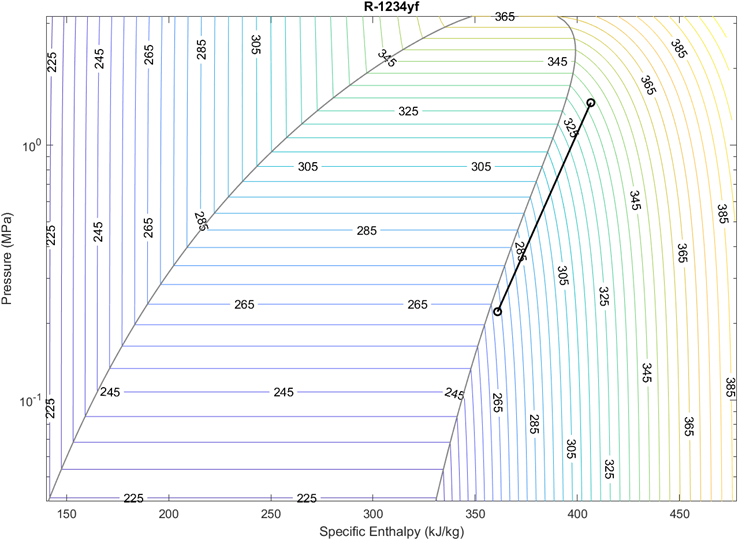

Figure 4: Pressure-enthalpy diagram for the compressor under nominal operating conditions.

Double-clicking on the P-H Diagram (2P) block shows the p/h diagram for the compressor at the nominal operating condition, as shown in Figure 4. As we might expect, the fluid heats as the pressure is increased because the compressor is performing work on it. The upper right circle on the plot indicates the resulting outlet state.

**Exercise. **What state(s) of matter are present in the compressor when it runs in a steady state, as in this model?

checkCompressorState("unknown")

 **Reflect**.

- Does the compressor run before or after the evaporator in the refrigeration cycle? 

- In what direction is this line oriented? Why? 

## Condenser

Now that we have set up the evaporator and compressor and determined their approximate heat loads, we can parameterize the condenser for the system. The evaporator and compressor will add about 1 kW and 0.5 kW of heat to the refrigerant, respectively, which means the condenser should be designed to dissipate about 1.5 kW of heat from the refrigerant to the environment. The worst-case scenario in our design specification is when the environmental temperature is at 40$^{\circ}$C, so we will parameterize the condenser under those conditions.

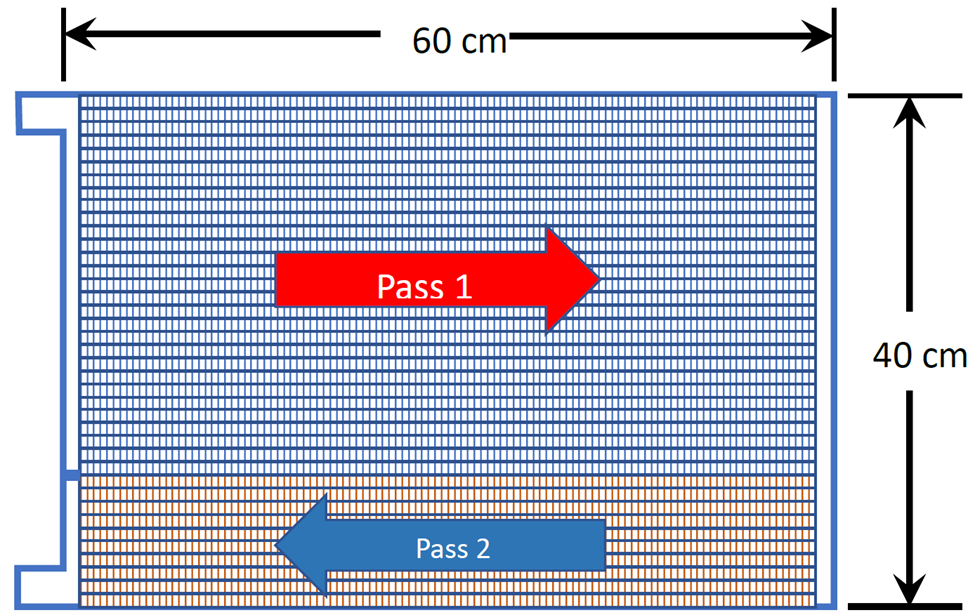

Figure 5: Two-pass condenser schematic. The refrigerant enters at the top and passes from left to right in the upper 30 banks of tubes, then right to left in the lower ten banks of tubes. There are three manifolds for the refrigerant, two on the left and one on the right. The air flows perpendicular to the plane of the image.

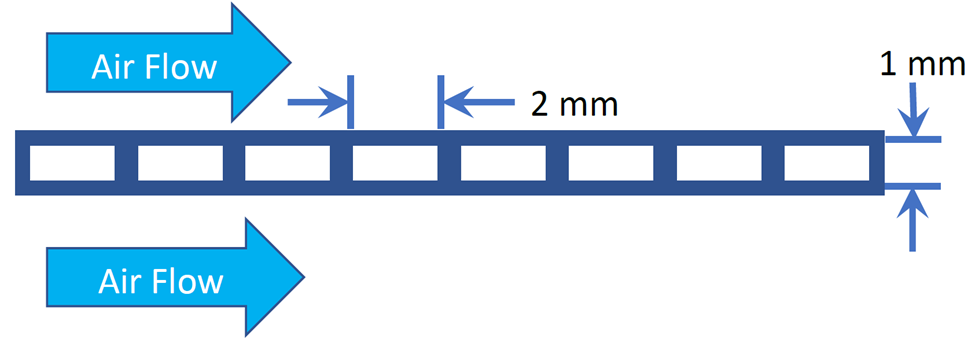

Figure 6: Refrigerant tube cutaway. The refrigerant flows into the plane of the document in the eight channels. There are fins on the top and bottom of each bank, which the air flows through to dissipate heat released by the condensing refrigerant.

The condenser to be modeled is a two-pass model with 30 banks in the first pass and ten in the second pass. The tube banks are arranged eight-per-row in line with fins that expel heat to the crossflow air stream. The configuration of the two refrigerant passes is shown in Figure 5, and the tube bank arrangement is shown in Figure 6. Assume the fins are independent of each other and aligned vertically with a density of five fins per centimeter, which is a reasonable approximation for this type of condenser hardware. This allows the calculation of $a_{\text{fins}}$.

The entrance and exits of the condenser and the connection between its two passes are represented as pipes. These pipes are not thermally connected but add capacitance to the condenser, which is crucial to preventing the tubes from flooding during high-temperature operations once the condenser is placed into the closed-loop system.

### Validate the Condenser Model

% Load the parameters
condenserParams;

% Open the model with sensor attachments
mdlCond = 'ModelFridgeCondenser';
open_system(mdlCond);

% Run the simulation
sim(mdlCond);

Double-clicking on the P-H Diagram (2P) block shows the P-H diagram for the condenser at the nominal operating condition.

** Exercise.**

- What is the orientation of this path on the P-H diagram?

tf1 = checkCondenserPath("unknown");

         2. What is the state of the R-1234yf when it enters the condenser?

tf2 = checkCondenserState("unknown","input");

         3. What is the state of the R-1234yf when it leaves the condenser?

tf3 = checkCondenserState("unknown","output");

#### **Check the Condenser Fluid State Fractions**

  **Try**.  Run this section to generate a plot of the condenser fluid state fractions. Do they match what you expect from the P-H diagram?

if ~tf1 || ~tf2 || ~tf3
    warning("Please complete the exercise before continuing.")
    % elseif ~exist("simout.simlog.Condenser.Pass_1.Z.series.time","var")
    %     warning("You must successfully simulate the condenser to proceed.")
else
    % Extract the data from the simulation and scale data to %
    tData = simlog_CondenserHarness.Pass_1.Z.series.time;
    pass1z = simlog_CondenserHarness.Pass_1.Z.series.values*100;
    pass2z = simlog_CondenserHarness.Pass_2.Z.series.values*100;

    % Plot the data with varying colors and line styles
    % Increase the line width for visibility and set the y scale
    clf
    plot(tData,pass1z(:,3),"-","SeriesIndex",1,"LineWidth",2)
    grid on
    ylim([40 60])
    hold on
    plot(tData,pass1z(:,2),"--","SeriesIndex",2,"LineWidth",2)
    plot(tData,pass2z(:,2),"-.","SeriesIndex",3,"LineWidth",2)
    plot(tData,pass2z(:,1),":","SeriesIndex",4,"LineWidth",2)
    hold off

    % Add labels
    legend(["Pass 1 SHV" "Pass 1 VLE" "Pass 2 VLE" "Pass 2 SCL"],"Location","east")
    title("Condenser Fluid State Fractions")
    xlabel("Time t (s)")
    ylabel("Z (%)")
end

As the fluid moves through the first pass of the condenser tubes, it begins to condense and enters the vapor-liquid equilibrium dome. In the second pass, the fluid crosses the saturated liquid boundary and leaves as a sub-cooled liquid. We plot selected state fractions of the fluids in the condenser passes to ensure the latter is true. From this figure, we can see that about 58% of the length of Pass 1 contains fluid in the super-heated vapor (SHV) state and 42% of Pass 1 contains fluid in the vapor-liquid equilibrium (VLE) state. In Pass 2, we see about 58% of the fluid is in the VLE state and the remaining 42% is already in the sub-cooled liquid (SCL) state. We are starting with a reasonable balance of vapor condensing to two-phase in Pass 1 and two-phase condensing to liquid without flooding the system in Pass 2. 

## Closing the Loop

Now that we have roughly sized the evaporator, compressor, and condenser, we’re ready to start closing the loop with the expansion device. It is important to note that the former three devices all change the system energy, whereas the expansion device is commonly treated as isenthalpic. It primarily allows the refrigerant to occupy a larger volume.

** Exercise.**

Which of the following P-H diagrams do you expect for this closed system?

a) 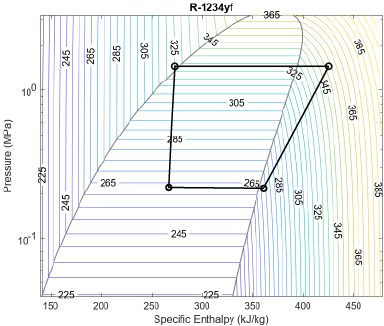   b)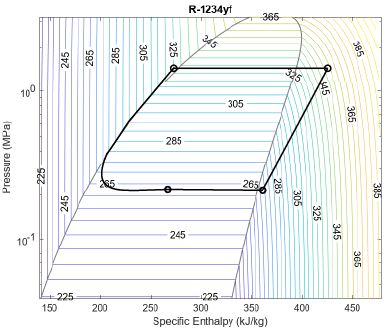    c) 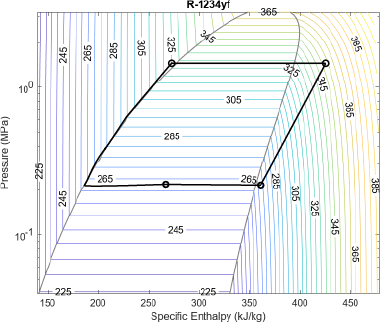

checkSystem("unknown")

**Isenthalpic** means that the specific enthalpy at the outlet to the condenser and the inlet to the evaporator should be the same. Before we close the loop, we’ll set up a system to ensure this for the steady state conditions specified in the design. Once the evaporator/compressor/condenser system is validated, we’ll parameterize and insert an expansion valve.

### Energy Cycle Validation

To ensure the parameters of the evaporator, compressor, and condenser are well-sized for their use together, we assemble them into a new harness model. This model is called `ModelFridgeEvapCompCond.slx.` It is shown in Figure 7. Note that we have assembled the individual parts to mirror the schematic in Figure 1, with the evaporator on the bottom, the condenser as a subsystem at the top and the compressor along the right side. This allows us to put the sensors in the order that they show up in the pressure/enthalpy diagram.

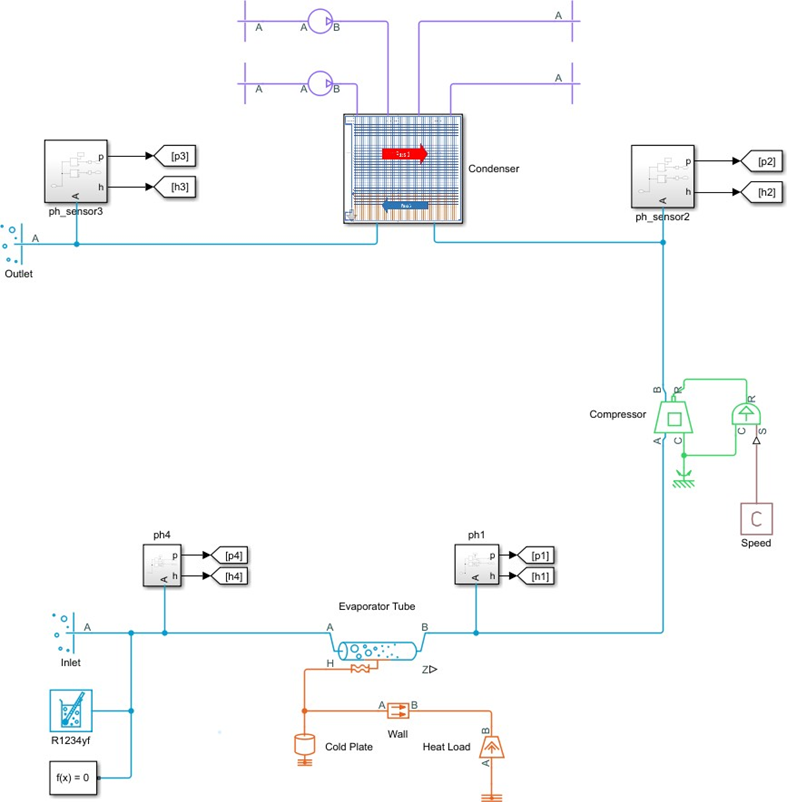

Figure 7: Energy balance test harness. This test harness provides a check to see that the evaporator, compressor, and condenser are in balance for the design cycle at steady state. Boundary conditions are set at the Inlet and Outlet blocks.

The block parameters for the Inlet and Outlet boundary condition blocks are the same parameters we used for each of the individual component tests. These are the approximate steady-state values for the design cycle. Note that the model still uses the steady state option in the Solver Configuration block. Once we add the final physical element, we will switch this off to model the proper dynamic behavior. 

% Open the model with sensor attachments
mdl = 'ModelFridgeEvapCompCond';
open_system(mdl);

% Load the parameters
evaporatorParams;
compressorParams;
condenserParams;

% Run the simulation
sim(mdl);

The resulting pressure/enthalpy diagram for the assembly is shown. As seen in this plot, the simulation behaves according to the design parameters. As expected, the evaporator outlet is slightly super-heated, and the condenser outlet is slightly sub-cooled.

  **Try**. Check the mass flow for this system using the Simscape Results Explorer (`sscexplorer). `The design value of a mass flow of 0.0104 kg/s should be close to (with 2%) your simulated values.

- Compressor $\rightarrow$ `mdot_A`

- CondOut $\rightarrow$ `mdot_A`

- EvapIn $\rightarrow$ `mdot_A`

- Evaporator Tube $\rightarrow$ `mdot_A`

 **Pro-tip. **To plot multiple values of `mdot_A` on the same axis in the Simscape Results Explorer, select each click each value while holding down the control key. 

 **Reflect**. Note that the signs of `mdot_A` differ for CondOut and EvapIn. Why?

## ** Example:** Add the Expansion Valve

Now that we have determined that the system energetics are balanced, we can parameterize and insert the expansion valve. In our application we will use an **Orifice (2P)** block. To have enough flexibility for a controller, we’ll size the valve so it has our approximate nominal desired flow rate (~0.01 kg/s) when it is halfway open, and the upstream and downstream pressures are 1464.7 kPa and 221.78 kPa, respectively. The parameters and boundary conditions for the valve use specific enthalpy inlet condition specifications as well as the usual "Start from steady state" solver configuration. As with the other harness models, we provide inlet and outlet reservoirs at the nominal operating conditions and solve at steady state. To validate the range of flows, we start the system with the valve fully open and use a ramp function to fully close it.

% Open the model with sensor attachments
mdl = 'ValveHarness';
open_system(mdl);

% Load the parameters
valveParams;

Run the simulation using a simple linear profile from the step function:

out = sim(mdl);

After running the simulation, extract data:

opening_fraction = out.simlog_ValveHarness.Valve.opening_area_fraction.series.values;
opening_length = opening_fraction*valve_max_open;
mdot = out.simlog_ValveHarness.Valve.mdot_A.series.values;

and plot the results:

plot(opening_length,mdot,"LineWidth",2)
yline(0.0104,"y--","LineWidth",2)

% Label the plot
title("Valve Characteristic")
xlabel("Position (mm)")
ylabel("Mass Flow Rate (kg/s)")
legend(["Simulated Valve" "Designed Mass Flow Rate"],"Location","northwest")

## Inserting the Valve

Now that we have parameterized the valve, we can insert it into our model and close the loop. Since all the components were put in test harnesses and sized appropriately, this step can be performed by placing the valve from `ValveHarness.slx` into the `ModelFridgeEvapCompCond.slx` model between the condenser outlet and evaporator inlet and removing the inlet and outlet reservoirs. This brings us back to the full refrigerator model, `ModelFridge.slx`, that we explored at the beginning. Now, however, we have parameter values chosen that allow us to simulate the model.

% Ensure that all parameters are loaded
evaporatorParams;
compressorParams;
condenserParams;
valveParams;

% Open the models with sensor attachments
fullmdl = 'ModelFridge';
open_system(fullmdl);

  **Try**. Run the full model.

sim(fullmdl);

Running this code generates errors. 

Check 1: If it fails to compile, check what refrigerant you are using. Remember that it should be R-1234yf per the design parameters.

Check 2: If it compiles but fails to run to completion and quickly diverges, that is correct at this point. We get a simulation failure at around 0.8 seconds. The error message mentions that we have exceeded the maximum valid specific internal energy for parts of our system. Watch the evolution of the system on the P-H diagram. As we approach the failure time, the P-H diagram is:

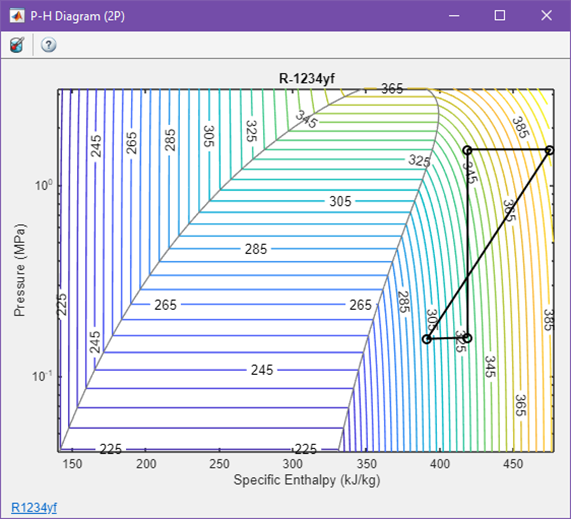

Figure 8: The closed loop P-H diagram at Time=0.8124 seconds. Notice that the circle in the upper left corner is about to leave the diagram. This indicates the model is about to exceed the maximum specific enthalpy in our fluid property tables.

If you open the Solver Configuration block, you will note that there is one another difference beyond simply combining the models we ran in ModelFridgeEvapCompCond.slx and ValveHarness.slx. In each of the earlier models, we were running our system from steady state. This is usually a more straightforward problem to solve mathematically and is of interest when a system will be running for an extended period of time. In the real world, though, devices get switched on and off, and the transient states that a system passes through on its way to a steady state can be vital to the stability and longevity of system components. In this case, the system does not have a stable solution because there is an error in our model that we will diagnose. 

 **Reflect**. 

- According to our model, what state is the refrigerant in at each sensor?  

- Can you explain why you might see such sensor readings? Does that help start trying to diagnose the fault in the system?

If you try checking "Start simulation from steady state" in the Solver Configuration block, the model will fail. 

### Diagnosing the Problem

Because this model didn't run to completion, we know there is an error somewhere in our assumptions. Rerun this model, stopping just before the error, and plot the data from each sensor for consideration:

out = sim(fullmdl, 'StopTime', '0.8');
% Extract the data for pressure and enthalpy for each sensor
timeData = out.simlog_ModelFridge.Sensor_1.Pressure_Internal_Energy_Sensor_2P.P.series.time;
sensor1pressure = out.simlog_ModelFridge.Sensor_1.Pressure_Internal_Energy_Sensor_2P.P.series.values;
sensor2pressure = out.simlog_ModelFridge.Sensor_2.Pressure_Internal_Energy_Sensor_2P.P.series.values;
sensor3pressure = out.simlog_ModelFridge.Sensor_3.Pressure_Internal_Energy_Sensor_2P.P.series.values;
sensor4pressure = out.simlog_ModelFridge.Sensor_4.Pressure_Internal_Energy_Sensor_2P.P.series.values;
sensor1enthalpy = out.simlog_ModelFridge.Sensor_1.Thermodynamic_Properties_Sensor_2P.H.series.values;
sensor2enthalpy = out.simlog_ModelFridge.Sensor_2.Thermodynamic_Properties_Sensor_2P.H.series.values;
sensor3enthalpy = out.simlog_ModelFridge.Sensor_3.Thermodynamic_Properties_Sensor_2P.H.series.values;
sensor4enthalpy = out.simlog_ModelFridge.Sensor_4.Thermodynamic_Properties_Sensor_2P.H.series.values;

% Plot the data you could also find in the Simscape Results Explorer
tl = tiledlayout(2,1);
title("Figure 9")
nexttile
plot(timeData,sensor1pressure,timeData,sensor2pressure,timeData,...
    sensor3pressure,timeData,sensor4pressure,"LineWidth",3)
grid on
title("Pressure Data")
subtitle("Observe that two components are nearly isobaric, so we only see two lines")
xlabel("Time (s)")
ylabel("Pressure (MPa)")
ylim([0 1.6])
xlim([timeData(1) timeData(end)])
legend(["Sensor 1" "Sensor 2" "Sensor 3" "Sensor 4"],"Location","east")
nexttile
plot(timeData,sensor1enthalpy,timeData,sensor2enthalpy,timeData,...
    sensor3enthalpy,timeData,sensor4enthalpy,"LineWidth",3)
grid on
xlabel("Time (s)")
ylabel("Specific Enthalpy (kJ/kg)")
ylim([200 500])
xlim([timeData(1) timeData(end)])
title("Enthalpy Data")
subtitle("Observe that one component is nearly isenthalpic, so we see only three lines")
legend(["Sensor 1" "Sensor 2" "Sensor 3" "Sensor 4"],"Location","southeast")
% Plot the location on the Pressure-Enthalpy plot of each sensor point
figure
title("Figure 10")
plot(sensor1enthalpy,sensor1pressure,"LineWidth",3)
hold on
plot(sensor2enthalpy,sensor2pressure,"LineWidth",3)
plot(sensor3enthalpy,sensor3pressure,"LineWidth",3)
plot(sensor4enthalpy,sensor4pressure,"LineWidth",3)
hold off
grid on
legend(["Sensor 1" "Sensor 2" "Sensor 3" "Sensor 4"],"Location","west")
xlabel("Specific Enthalpy (kJ/kg)")
ylabel("Pressure (MPa)")

 **Reflect**. In a steady-state system, what would you expect the pressure-enthalpy plot in Figure 10 to look like?

** Exercise. **Figure 8 indicates that one of the sensors is registering values that are off the data tables we are using. By referring to the data in Figures 9 and 10, which sensor is it?

sensorBetweenComponents("unknown")

The root cause for the error is not in the sizing of the system components but instead in how we have defined its initial conditions. As we will see in the next section, our system is severely undercharged with refrigerant. If we could create a real system in this state, we would find it would rapidly overheat and fail catastrophically. In the next section, we’ll diagnose and fix the problem. In the simulation, we observe an unexpected set of initial conditions for the enthalpies, resulting in state diagram plots that should look incorrect to you, even at time 0.

## Charging the System

To understand the simulation failure, we first need to consider the total system volume and amount of refrigerant in the `ModelFridge.slx` model. To do this, we can set the model Stop Time to zero and simulate it. Then we can interrogate the simulation log for blocks with internal volume nodes. These are the blocks that will have mass in the simulation, and they are:

- Condenser manifolds – Pipe (2P)

- Condenser heat exchangers – Condenser Evaporator (2P-MA)

- Evaporator – 3-Zone Pipe (2P)

  **Try**. Make sure the model is open and its parameters are loaded, then simulate for zero seconds so the refrigerant blocks with volume compute their masses.

% Make sure all the parameters are loaded
evaporatorParams;
compressorParams;
condenserParams;
valveParams;

fullmdl = 'ModelFridge';
open_system(fullmdl);
out = sim(fullmdl, 'StopTime', '0');

Identify the condenser masses for the manifolds and heat exchanger blocks:

mm1 = out.simlog_ModelFridge.Condenser.Manifold_1.mass.series.values('kg');
mm2 = out.simlog_ModelFridge.Condenser.Manifold_2.mass.series.values('kg');
mm3 = out.simlog_ModelFridge.Condenser.Manifold_3.mass.series.values('kg');
mp1 = out.simlog_ModelFridge.Condenser.Pass_1.two_phase_fluid_1.mass.series.values('kg');
mp2 = out.simlog_ModelFridge.Condenser.Pass_2.two_phase_fluid_1.mass.series.values('kg');


Identify the mass in the evaporator tube:

me = out.simlog_ModelFridge.Evaporator_Tube.mass.series.values('kg');

** Exercise. **Compute the total mass, `mass_total` in kilograms:

mass_total = 0;

Recall that the geometric dimensions we know are:

Compute the volume of the manifolds and heat exchangers in cubic meters:

  **Pro-tip**. The function [`sum`](matlab: doc sum) will add up all of the components of a vector.

v_manif = sum(a_man*l_man)/(100*100*100);                  % [m^3]
v_hx = sum(N_tube_pass*l_tube*a_tube)/(100*1000*1000);     % [m^3]

Compute the volume of the evaporator in cubic meters:

v_evap = l_evap*a_evap/(100*100);                          % [m^3]

Compute the total system volume, `v_total`, in cubic meters:

v_total = 0;

Compute the system density `rho`. Ideally, this should be between 200 and 300 $\frac{\text{kg}}{\text{m}^3}$ for R1234yf.

rho = 0;

% Use this function to check your results
checkDensity(mass_total,v_total,rho)

** Exercise. **Given the calculated mass, volume, and density values, is this system currently undercharged or overcharged?

systemIs("unknown")

To compute the correct system density for the system at rest in some ambient condition, we need to consult the property tables for the fluid. In our case, we’ll start our system out in the worst-case environment at T=40$^{\circ}$C. As usual, we need to convert the pascals in our database to kilopascals that we are using in our model

load R1234yfData p0        % Pa
                           % kPa

This gives us the initial pressure condition for the pipes and heat exchangers.

** Exercise. **To be effective, when the system is at rest the refrigerant must be in the following state(s):

initialState("unknown");

#### ** Example: Complete the Calculation of the Initial Quality**

With this in mind, we will specify the initial vapor quality in the pipes and heat exchangers. To compute the initial system quality, we can query a thermal properties database with the worst-case temperature Twc=40$^{\circ}$C and density=200 kg/m^3. 

Alternatively, if we know the vapor and liquid densities at the given temperature, we can interpolate to determine the initial quality. 

load R1234yfData rho_l rho_v          % kg/m^3
disp("For R1234yf at 40C we have a liquid density of rho_l=" + rho_l + ...
    newline + "and a vapor density of rho_v=" + rho_v + ".")

To compute the vapor quality required to achieve our target density of $\rho_{\text{ref}}=200$ kg/m^3, we can use the following equation:


$$\rho_{\text{ref}} = \frac{1}{\frac{x_0}{\rho_v} + \frac{1-x_0}{\rho_l}},$$


and solve for $x_0$

rho_ref = 200;                        % kg/m^3
fun = @(x) rho_ref-1/(x/rho_v + (1-x)/rho_l);
% initial quality fraction
x0 = fzero(fun,0.5)                   %#ok<NASGU> Suppress warning for displayed variable

## Running the Closed Loop

  **Try**. When we set the initial conditions for the properly charged system and run it, we can see that the system stabilizes to a place that reflects our design. The steady-state cycle can be viewed in the P-H Diagram. The condenser provides fully condensed refrigerant, and the evaporator provides super-heated vapor to the compressor.

% First closed-loop model parameter set
evaporatorParams;
compressorParams;
condenserParams;
valveParams;

% New initial pressure at T0 = 40 degC
p0 = 1018.4;     % [kPa]

% Liquid and vapor densities at 40 degC
rho_l = 1034;    % [kg/m^3]
rho_v = 57.75;   % [kg/m^3]

% Target density
rho_ref = 200;   % [kg/m^3]

% Set up and solve for x0 for the target density
fun = @(x)rho_ref-1/(x/rho_v + (1-x)/rho_l);
x0 = fzero(fun, 0.5);

fullmdl = 'ModelFridge_WithQuality';
open_system(fullmdl);
try
    simout = sim(fullmdl);
catch ME
    if exist("MaskFailure","var")
        clear MaskFailure
        rethrow(ME)
    else
        MaskFailure = ME;
        % Rerun to update mask parameters properly
        simout = sim(fullmdl);
    end
end

## Further Exploration

  **Try**. 

- Without tuning this refrigerator for other refrigerants, can you test whether any other refrigerants work by changing the Two-phase fluid parameter in the Two-phase Fluid Choice block? 

- If you have access to [CoolProp](matlab: edit SetUpCoolProp.mlx), does the refrigerator performance improve if you update parameters for the new refrigerant rather than R-1234yf?

[⇦ Return to the navigation page](matlab: OpenOverview)

## References

- **Lemmon, E.W., Bell, I.H., Huber, M.L., McLinden, M.O. ***NIST Standard Reference Database 23: Reference Fluid Thermodynamic and Transport Properties-REFPROP, Version10.0, National Institute of Standards and Technology. *Gaithersburg, MD, USA: s.n., 2018.

- **Bell, Ian H. and Wronski,Jorrit and Quoilin,Sylvain and Lemort,Vincent. **Pure and Pseudo-pure Fluid Thermophysical Property Evaluation and the Open-Source Thermophysical Property Library CoolProp. *Industrial & Engineering Chemistry Research. *2014, Vol. 53, 6, pp. 2490-2508.

function initialState(opt)
if opt == "unknown"
    disp("This is the default value. Please select a state.")
elseif opt == "vapor-liquid mixture"
    disp("That is correct. This allows sufficient phase transition to perform" + ...
        newline + "the cooling task.")
elseif opt == "depends on the component"
    disp("That is incorrect. The state (or mix of states) must be the same.")
elseif opt == "vapor"
    disp("That is incorrect." + newline + "If the initial state was vapor," + ...
        " it could not form sufficient liquid.")
elseif opt == "liquid"
    disp("That is incorrect. If the initial state was liquid, it could not vaporize" + ...
        newline + "because there is no space.")
else
    disp("How did you get here?")
end
end

function systemIs(opt)
if opt == "unknown"
    disp("This is the default value. Please select undercharged or overcharged.")
elseif opt == "undercharged"
    disp("The current density is about 56 kg/m^3 which is less than 200 kg/m^3." + ...
        newline + "You are correct, this system is undercharged.")
elseif opt == "overcharged"
    disp("The current density is about 56 kg/m^3 which is less than 200 kg/m^3." + ...
        newline + "A system is overcharged if the density is too high."  + ...
        newline + "This system is not overcharged.")
end
end

function checkDensity(my_mass_total,my_v_total,my_rho)
load densityValues.mat mass_total v_total rho
if my_mass_total == mass_total && my_v_total == v_total && my_rho == rho
    disp("Mass of Refrigerant: " + my_mass_total + " kg");
    disp("Total System Volume: " + my_v_total + " m^3");
    disp("System Density: " + my_rho + " kg/m^3");
elseif my_mass_total == 0 && my_v_total == 0 && my_rho == 0
    disp("These are the default values. Please compute real values.")
else
    if my_mass_total ~= mass_total
        disp("Your total mass is incorrect.")
    end
    if my_v_total ~= v_total
        disp("Your total volume is incorrect.")
    end
    if my_rho ~= rho
        disp("Your density is incorrect.")
    end
end
end

function tf = checkCondenserPath(opt)
tf = 0;
if opt == "unknown"
    disp("This is the default. Please select a direction.")
elseif opt == "left to right"
    disp("Remember that the R-1234yf is flowing from the compressor into" + ...
        newline + "the condenser. Where is the path of the compressor?")
elseif opt == "right to left"
    disp("That is correct. The R-1234yf has just come from the compressor" + ...
        newline + "which raised the pressure and is passing through the condenser" + ...
        newline + "which lowers the enthalpy.")
    tf = 1;
else
    disp("How did you get here? That was an unexpected option.")
end
end

function tf = checkCondenserState(opt,dir)
tf = 0;
if opt == "unknown"
    disp("This is the default. Please select a state.")
elseif opt == "solid"
    disp("This diagram does not include the solid state. Please try again.")
elseif opt == "sub-cooled liquid"
    if dir == "output"
        disp("That is correct.")
        tf = 1;
    else
        disp("The sub-cooled liquid region is on the left." + ...
            newline + "Where is the initial state? And the final state?" + ...
            newline + "Please try again.")
    end
elseif opt == "liquid-vapor mixture"
    disp("The liquid-vapor mixture region is in the center." + ...
        newline + "Where is the initial state? And the final state?" + ...
        newline + "Please try again.")
elseif opt == "super-heated vapor"
    if dir == "input"
        disp("That is correct.")
        tf = 1;
    else
        disp("The super-heated vapor region is on the right." + ...
            newline + "Where is the initial state? And the final state?" + ...
            newline + "Please try again.")
    end
elseif opt == "plasma"
    disp("This diagram does not include the solid state. Please try again.")
else
    disp("How did you get here? That was an unexpected option.")
end
end

function checkSystem(opt)
if opt == "a"
    disp("That is correct. Isenthalpic means that the enthalpy should be constant.")
elseif opt == "unknown"
    disp("This is the default. Please select a P-H diagram.")
else
    disp("No, this is not an isenthalpic line. Please try again.")
    disp("An expansion valve allows the refrigerant to occupy more volume.")
    disp("Do you expect this to change the enthalpy or the pressure more visibly?")
end
end

function sensorBetweenComponents(opt)
if opt == "unknown"
    disp("This is the default. Please select Sensor 1, 2, 3, or 4.")
elseif opt == "ph2"
    disp("This is correct.")
elseif opt == "ph3"
    disp("You would expect the sensor in the top-left, initially, on the P-H diagram" + ...
        newline + "to be Sensor 3, but because this model is failing to simulate properly," + ...
        newline + "that is incorrect." + ...
        newline + "Which sensor is registering the highest enthalpy value in Figure 9?")
else
    disp("This is not correct." + newline + "In Figure 9, which sensor is registering" + ...
        + "the highest enthalpy value?")
end
end

function checkEvaporatorExercise(a1,opt)
switch opt
    case "a)"
        soln = 221;
        bound1 = 1;
        bound2 = 100;
    case "b)"
        soln = 265;
        bound1 = 1;
        bound2 = 10;
    case "c)"
        soln = 361;
        bound1 = 1;
        bound2 = 10;
end
if opt ~= "d)"
    if a1 == 0
        disp("This is the default value. Please answer question " + opt + ".")
    elseif abs(a1-soln) < bound1
        disp("Excellent work. Your answer is a very good estimate.")
    elseif abs(a1-soln) < bound2
        disp("That is a reasonable estimate, especially if you just read it off the graph.")
    elseif opt == "a)" && abs(a1) < 1
        disp("Your answer is supposed to be in kPa, but you seem to have answered in MPa.")
    else
        disp("Your answer is not correct. Remember that the y-axis is scaled logarithmically,")
        disp("and the x-axis is scaled linearly. The enthalpy is on the x-axis.")
    end
else
    if a1 == "default"
        disp("This is the default value. Please answer question " + opt + ".")
    elseif a1 == "warmer"
        disp("This is incorrect. What are the units of temperature here?")
    elseif a1 == "colder"
        disp("You are correct that 263K at the inlet and 268K at the outlet are both" + ...
            newline + "colder than the freezing point of water at 273.15K.")
    elseif a1 == "both"
        disp("This is incorrect. The values range from 263K to 268K." + ...
            newline + "What is the freezing temperature of water?")
    else
        warning("How did you get here?")
    end
end
end

function checkCompressorState(opt)
switch opt
    case "unknown"
        disp("This is the default value. You have enough information to say more.")
    case "solid"
        disp("No, there should not be any solid refrigerant in a refrigeration cycle.")
    case "liquid"
        disp("No, liquid is not compressible. If there were liquid filling the compressor it")
        disp("would likely break quickly.")
    case "gas"
        disp("That is correct. The compressor is responsible for increasing the" + ...
            newline + "pressure of the gaseous refrigerant at a fairly stable enthalpy value.")
    case "two-phase"
        disp("While you could run a vapor/liquid mixture through the compressor, the " + ...
            newline + "liquid would erode the components of the compressor which would shorten" + ...
            newline + "the lifespan of your refrigerator. In a well-designed system, there" + ...
            newline + "should be no liquid passing through the compressor in steady state.")
    case "supercritical"
        disp("The operating conditions for this refrigeration cycle are close to" + ...
            newline + "standard temperature and pressure. The refrigerant should not" + ...
            newline + "be supercritical anywhere in this cycle.")
end
end

function [x,y] = collectData()
% axes('position',[0 0 1 1]);
imshow("ThermEntropy.png")
% str = ["Select sensor values around the diagram by clicking and then double-click ", ...
%     "to finish data collection. Close the figure window to return to the script."];
% annotation("textbox",[.05 .9 .1 .1],"String",str,"FitBoxToText","on")
ax = gca;
roi = drawpolygon(ax);
x = roi.Position(:,1);
y = roi.Position(:,2);
end

function tf = checkEstimatedCycle(x,y)
if length(x) == 5
    if x(1)==x(end) && y(1)==y(end)
        x = x(1:end-1);
        y = y(1:end-1);
    elseif x(end-1) == x(end) && y(end-1) == y(end)
        x = x(1:end-1);
        y = y(1:end-1);
    end
elseif length(x) ~= 4
    warning("You did not identify 4 points in the pop-up window."...
        +newline+"After you have identified four points, double-click" ...
        + " the first point" + newline+ "to identify the full cycle.")
end
load("twophasecurve.mat","tpX","tpY")
inTwoPhase = inpolygon(x,y,tpX,tpY);
inLiquid = inpolygon(x,y,[tpX(1:29); tpX(1); tpX(1)],[tpY(1:29); tpY(29); tpY(1)]);
inGaseous = inpolygon(x,y,[tpX(30:end); 835; 835; tpX(30)],...
    [tpY(30:end); tpY(end); tpY(30); tpY(30)]);

states = ["gaseous" "liquid" "two-phase"];
tf = [0 0 0];

for k = 1:3
    myState = states(k);
    myStr = "one point";
    myCount = 1;
    switch myState
        case "gaseous"
            myPhase = inGaseous;
            myCount = 2;
            myStr = "two points";
        case "liquid"
            myPhase = inLiquid;
        case "two-phase"
            myPhase = inTwoPhase;
    end
    if sum(myPhase)==myCount
        disp("Yes, there should be " + myStr + " in the "+ myState + " region.")
        tf(k) = 1;
    elseif sum(myPhase) > myCount
        disp("You identified too many points in the "+ myState + " region.")
    else
        disp("You identified too few points in the "+myState + " region.")
    end
end

if all(tf)
    twophasePt = y(inTwoPhase);
    liquidPt = y(inLiquid);
    % Note that the y-data is collected from the top of the image
    if twophasePt > liquidPt
        disp("Good work. Can you identify which of these points could be Sensor 4?")
        imshow("ThermEntropy.png")
        hold on
        plot(x',y',"o",MarkerFaceColor="b")
        hold off
        myLabels = ["a)" "b)" "c)" "d)"];
        for k = 1:4
            text(x(k)+5,y(k),myLabels(k),"FontSize",20,"FontWeight","bold")
        end
    else
        tf = [tf 0];
        disp("Why is the pressure of your two-phase point higher" + ...
            newline + "than the pressure of your liquid point?")
        disp("What happens to the refrigerant when it goes through an expansion valve?")
        disp("Please rerun the previous section to select new points.")
    end
else
    disp("Please rerun the previous section to select new points.")
end

end

function checkSensorPoints(sensor4,x,y)
if sensor4 == 0
    disp("You only have four points. One of these values corresponds to Sensor 4.")
    disp("Which one?")
else
    load("twophasecurve.mat","tpX","tpY")
    inTwoPhase = inpolygon(x(sensor4),y(sensor4),tpX,tpY);
    if inTwoPhase
        disp("Correct! Sensor 4 is in between the expansion valve and the evaporator and it should")
        disp("register two-phase values.")
    else
        disp("This is not a reasonable choice for Sensor 4. Remember that Sensor 4 comes after the")
        disp("expansion valve so the pressure should be low. It also comes before the evaporator so")
        disp("there should be more liquid and less vapor.")
    end
end
end

function checkMyParams(mhout,Tsh,mPevap,Tevap,mhin,Tsc,mPcond,Tcond,kelvinCelsiusShift)
if kelvinCelsiusShift == 0
    disp("You are expected to use kelvinCelsiusShift to convert temperatures."...
        + newline + "The value of kelvinCelsiusShift is not 0.")
elseif kelvinCelsiusShift == 273.15
    disp("The kelvinCelsiusShift value is correct.")
elseif abs(kelvinCelsiusShift-273.15)<1
    disp("You must be more precise." +newline ...
        + "Please give the Kelvin to Celsius shift to two decimal places of accuracy.")
elseif kelvinCelsiusShift < 0
    disp("The kelvinCelsiusShift should be a positive number.")
else
    disp("You have an incorrect value of the Kelvin to Celsius shift." + ...
        newline + "Please look up this value in the literature.")
end
giveTempFeedback(Tcond,55,"Tcond")
load R1234yfData Pcond Pevap hin hout   % Pa Pa J/kg J/kg
giveFeedback(mPcond,Pcond,"Pcond","Pa","kPa")
giveTempFeedback(Tsc,55-8,"Tsc")
giveFeedback(mhin,hin,"hin","J/kg","kJ/kg")
giveTempFeedback(Tevap,-10,"Tevap")
giveFeedback(mPevap,Pevap,"Pevap","Pa","kPa")
giveTempFeedback(Tsh,-10+5,"Tsh")
giveFeedback(mhout,hout,"hout","J/kg","kJ/kg")
end

function giveTempFeedback(myT,TinC,myStr)
if myT == TinC+273.15
    disp("The value of "+myStr+" is correct.")
elseif abs(myT-(TinC+273.15))<1
    disp("You appear to be rounding your value of "+myStr+"." + ...
        newline + "It should be correct to two decimal places.")
elseif myT == TinC
    disp("This is the value of "+myStr+" in Celsius," + ...
        newline + "but we want the value of "+myStr+" in Kelvin.")
else
    disp("You have an incorrect value of "+myStr+".")
end
end

function giveFeedback(myVal,baseVal,myStr,unit1,unit2)
if myVal == baseVal
    disp("You need to convert " + myStr + " from " + unit1 + " to "+ unit2 + ".")
elseif myVal == baseVal/1e3
    disp("Your value for "+myStr+" is correct in "+ unit2 + ".")
elseif myVal == baseVal*1e3
    disp("You appear to have multiplied rather than dividing when defining " + myStr + "." ...
        +newline+ "Please fix this before continuing.")
else
    disp("Your value for " + myStr + " is incorrect.")
end
end